# Curve fitting stability

The goal is to verify that our curve fitting is consistent when the total number of neurons increases, and that the fit recapitulates facts that are true by construction.

## Validating the IMSE metric

The simulated datasets have one parameter that we will vary freely, the common input noise to all the neurons. In the limit of infinite neurons, the decoding accuracy will be exactly the accuracy of the common input noise. We can simulate that scenario by having one neuron that only has input noise but no output noise. The accuracy of the input noise should match the IMSE accuracy.

sigma_vals = logspace(-1,4,150);
rmse_vals = arrayfun(@sigma2rmse, sigma_vals);

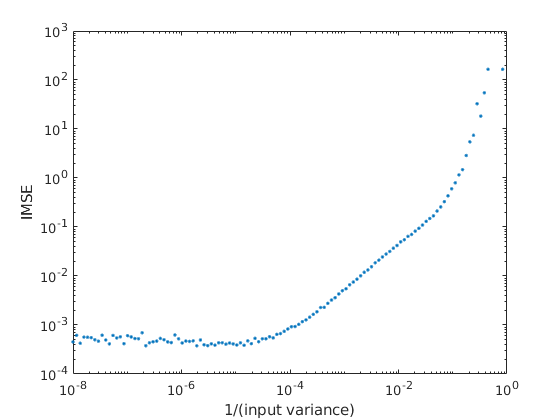

figure;
loglog(1./sigma_vals.^2, 1./rmse_vals.^2, '.');
xlabel '1/(input variance)'
ylabel 'IMSE'

We can see that there is a linear correspondence between 1e-4 and 0.01 inverse input variance. These values correspond to:

low_IIV_bound = 1e-4

low_IIV_bound = 1.0000e-04

high_IIV_bound = 0.01

high_IIV_bound = 0.0100


low_IMSE_bound = iiv2imse(low_IIV_bound)

low_IMSE_bound = 8.6669e-04

high_IMSE_bound = iiv2imse(high_IIV_bound)

high_IMSE_bound = 0.0459

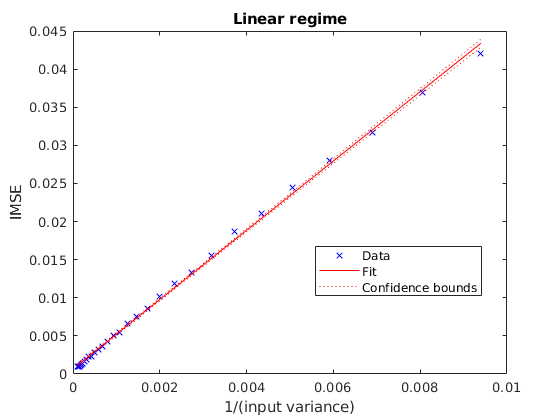


[iiv_vals, ord] = sort(1./sigma_vals.^2);
imse_vals = 1./rmse_vals(ord).^2;

linear_range_begin = find(iiv_vals > low_IIV_bound, 1);
linear_range_end = find(iiv_vals > high_IIV_bound, 1) - 1;

iiv_vals = iiv_vals(linear_range_begin:linear_range_end);
imse_vals = imse_vals(linear_range_begin:linear_range_end);

mdl = fitlm(iiv_vals, imse_vals);
figure;
plot(mdl);
xlabel '1/(input variance)'
ylabel 'IMSE'
title 'Linear regime'

mdl

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)    0.0006812    0.00011161    6.1032    1.3872e-06
    x1                 4.545      0.033534    135.53    5.3503e-41


Number of observations: 30, Error degrees of freedom: 28
Root Mean Squared Error: 0.000464
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 1.84e+04, p-value = 5.35e-41

to_imse_const = mdl.Coefficients.Estimate(2)

to_imse_const = 4.5450

The relationship is nearly proportional, with a constant of ~4.5. We will only fit curves to IMSE values that are within the linear regime.

## Fit stability with changing maximum ensemble size

We would now like to construct simulated data with input noise of a standard deviation of 10cm, and to be able to recapitulate this property from the decoding curves using 500 (low) and 2000 (high) neurons.

sigma = 10;
[n_low, mse_low, ~, fr_low, gof_low] = general_decoding_curve('n_cells', 500, 'noise_sigma', sigma, 'linear_only', true, 'approx_samp', 50);

[n_high, mse_high, ~, fr_high, gof_high] = general_decoding_curve('n_cells', 2000, 'noise_sigma', sigma, 'linear_only', true, 'approx_samp', 50);

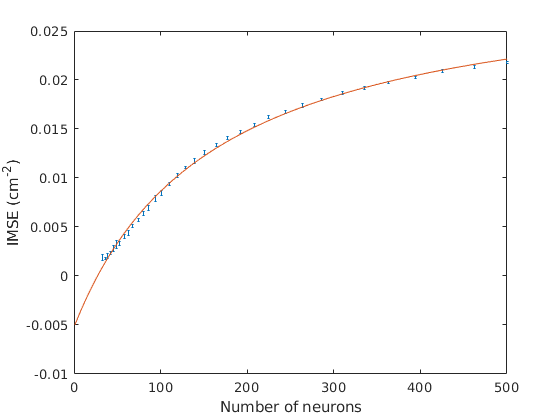

figure;
ep(n_low, 1./mse_low);
hold on;
plot(1:max(n_low), fr_low(1:max(n_low)));
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'

fr_low

fr_low =      General model:
     fr_low(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =    0.000225  (0.000201, 0.000249)
       N =       160.7  (142.3, 179.1)
       c =   -0.005227  (-0.006025, -0.004428)

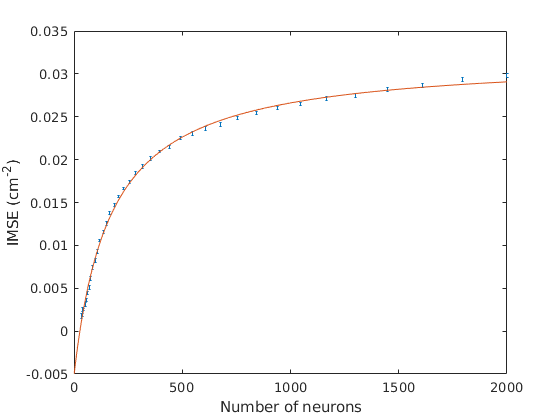

figure;
ep(n_high, 1./mse_high);
hold on;
plot(1:max(n_high), fr_high(1:max(n_high)));
xlabel 'Number of neurons'
ylabel 'IMSE (cm^{-2})'

fr_high

fr_high =      General model:
     fr_high(n) = I_0*n / (1 + n/N) + c
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0002215  (0.000204, 0.000239)
       N =       167.6  (155.8, 179.3)
       c =   -0.005174  (-0.005887, -0.004461)

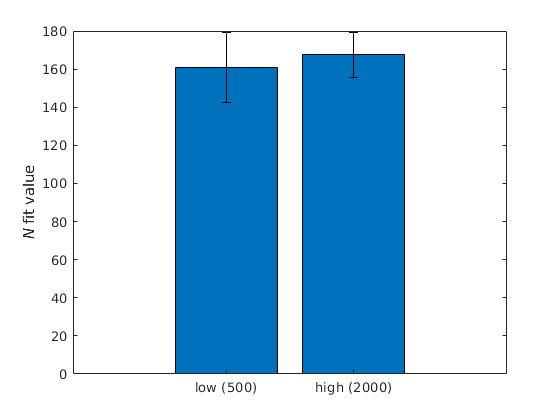

figure;
c = {'low (500)', 'high (2000)'};
N_vals = [fr_low.N fr_high.N];
N_conf = [get_ci(fr_low,'N') get_ci(fr_high, 'N')];
barerr([1 2], N_vals, N_conf);
ylabel '{\itN} fit value'
set(gca, 'XTickLabel', c)

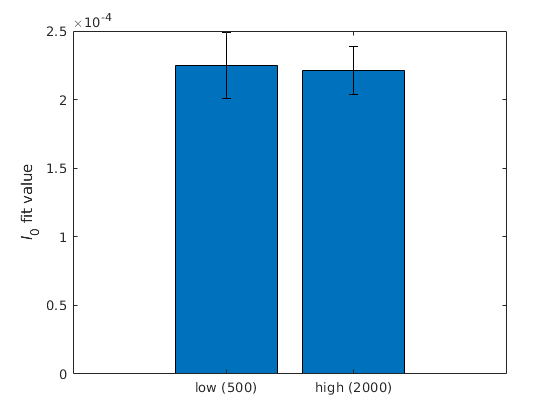


figure;
I0_vals = [fr_low.I_0 fr_high.I_0];
I0_conf = [get_ci(fr_low,'I_0') get_ci(fr_high, 'I_0')];
barerr([1 2], I0_vals, I0_conf);
ylabel '{\itI}_0 fit value'
set(gca, 'XTickLabel', c)

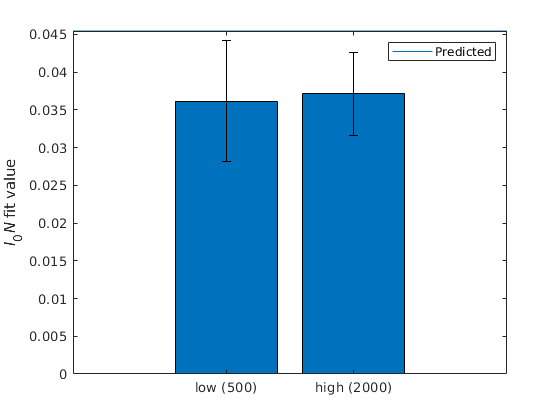


figure;
I0N_vals = I0_vals.*N_vals;
I0N_conf = I0_vals.*N_conf + N_vals.*I0_conf;
barerr([1 2], I0N_vals, I0N_conf);
ylabel '{\itI}_0{\itN} fit value'
set(gca, 'XTickLabel', c)

l_ = refline(0, to_imse_const./sigma.^2);

legend(l_, 'Predicted');

## Varying the input noise

The next check is to see whether the curve fitting is able to characterize a range of input noise values.

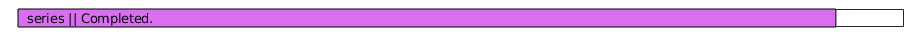

s_values = 0:2.5:30;
progressbar('series')
for i = 1:numel(s_values)
    [n_series{i}, mse_series{i}, ~, fr_series{i}, gof_series{i}] = general_decoding_curve('approx_samp', 50, 'n_min', 10, 'n_cells', 500, 'noise_sigma', s_values(i), 'n_reps', 16, 'linear_only', true);
    [~, limit_mse{i}] = general_decoding_curve('approx_samp', 1, 'n_cells', 10e3, 'noise_sigma', s_values(i), 'linear_only', false, 'n_reps', 16);
    progressbar(i/numel(s_values));
end

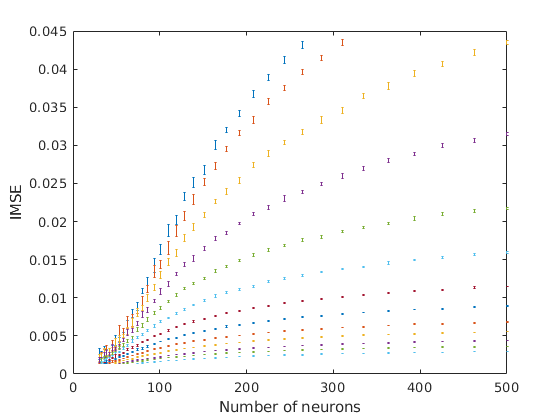

figure;
for i = 1:numel(s_values)
    ep(n_series{i}, 1./mse_series{i}); hold on;
end
xlabel 'Number of neurons'
ylabel 'IMSE'

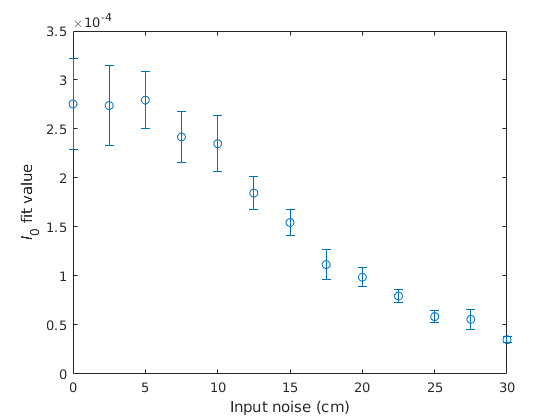


figure;
errorbar(s_values, cellfun(@(x)x.I_0, fr_series), cellfun(@(x)get_ci(x,'I_0'), fr_series), 'o');
xlabel 'Input noise (cm)'
ylabel '{\itI}_0 fit value'

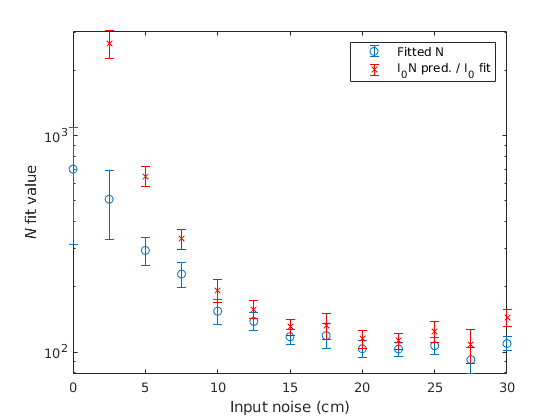

figure;
errorbar(s_values, cellfun(@(x)x.N, fr_series), cellfun(@(x)get_ci(x,'N'), fr_series), 'o');

hold on;
I0_series_values = cellfun(@(x)x.I_0, fr_series);
I0_series_conf = cellfun(@(x)get_ci(x,'I_0'), fr_series);
N_from_prediction = to_imse_const./s_values.^2 ./ I0_series_values;
N_pred_err = N_from_prediction .* I0_series_conf ./ I0_series_values;
errorbar(s_values, N_from_prediction, N_pred_err, 'xr');

legend 'Fitted N' 'I_0N pred. / I_0 fit'
xlabel 'Input noise (cm)'
ylabel '{\itN} fit value'
set(gca, 'YScale', 'log')

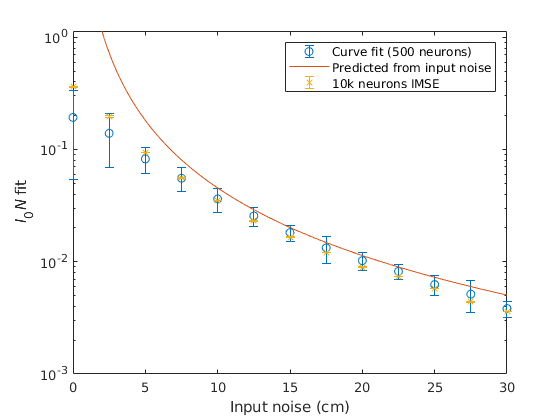

figure;
I0N_series = cellfun(@(x)x.N*x.I_0, fr_series);
I0N_conf = cellfun(@(x)x.I_0*get_ci(x,'N') + x.N*get_ci(x,'I_0'), fr_series);
errorbar(s_values, I0N_series, I0N_conf, 'o');
hold on;
x_ = 2:0.01:30;
plot(x_, to_imse_const./x_.^2);

lim_mean = cellfun(@(x)mean(1./x), limit_mse);
lim_conf = 1.96*cellfun(@(x)std(1./x), limit_mse)./sqrt(cellfun(@numel, limit_mse));

errorbar(s_values, lim_mean, lim_conf, 'x');

legend 'Curve fit (500 neurons)' 'Predicted from input noise' '10k neurons IMSE'
xlabel 'Input noise (cm)'
ylabel '{\itI}_0{\itN} fit'
set(gca, 'YScale', 'log')

function rmse = sigma2rmse(sigma)
[~, mse] = general_decoding_curve('noise_sigma', sigma,...
    'approx_samp', 1,...
    'n_reps', 1,...
    'n_cells', 1,...
    'response_type', "gaussian",...
    'model_type', "rate coding",...
    'progress', false); 
rmse = sqrt(mean(mse));
end

function imse = iiv2imse(iiv)
sigma = 1./sqrt(iiv);
rmse = sigma2rmse(sigma);
imse = 1./rmse.^2;
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end

function ci = get_ci(fit_mdl, varname)
names = coeffnames(fit_mdl);
idx = find(strcmp(names, varname));
assert(numel(idx) == 1, 'Variable not found');

q = confint(fit_mdl);
q = q(:,idx);
ci = (q(2) - q(1))/2;
end